# **IMPLEMENTAZIONE E TESTING DELLA PROCEDURA DI BACKTRACKING PER LINE SEARCH APPROSSIMATA NEL METODO STEEPEST DESCENT.**

Studente: Biagio Torsello, s269619.

L'elaborato è suddiviso in **una serie di paragrafi**, nei quali si espone l'analisi dei risultati ottenuti dalla procedura di backtracking nel metodo steepest descent al variare dei parametri in input per una delle funzioni test solitamente utilizzate in ottimizzazione, ossia **la funzione di Rosenbrock** ("banana function") , in 2 dimensioni.

L'elaborato è dunque organizzato secondo la **seguente struttura**:

- forma analitica della funzione in esame, relativo grafico e rappresentazione delle curve di livello. Inoltre, è anche presente l'espressione analitica del gradiente esatto della funzione, che verrà utilizzato nell'implementazione del backtracking;

- elenco dei dati utilizzati per il testing, ovvero i valori di $\alpha_0$, t e c che veranno utilizzati per testare la procedura implementata. Essi si riferiscono rispettivamente al passo iniziale della line search, al cosidetto "parametro target" che compare nella stima del target di decrescita della funzione, ed al parametro di contrazione del passo;

- seguono una serie di paragrafi in cui vengono esposti i risultati ottenuti in forma tabellare: l'idea è quella di tenere costanti due dei tre parametri, e vedere in che modo varia il numero di iterazioni al variare del parametro "libero". Si vuole in tal modo cercare di avere un'idea generale del modo in cui la prestazione cambia a seconda dei parametri in input;

- conclusione: commento dei risultati ottenuti.

Infine, al fondo dell'elaborato è presente **l'implementazione** della procedura di backtracking per la funzione di Rosenbrock, corredata da una breve documentazione esplicativa.

## **FUNZIONE DI ROSENBROCK ("BANANA FUNCTION").**

  1. **Panoramica generale della funzione di Rosenbrock (in due dimensioni).**

$\;\;f\left(x,y\right)=100\cdot {\left(y-x^2 \right)}^2 +{\left(1-x\right)}^2$ ;

$\;\;\nabla f\left(x,y\right)=\left(-400\cdot \left(y-x^2 \right)\cdot x\;-\;2\cdot \left(1-x\right)\;\;\;\;;\;\;\;\;\;200\cdot \left(y-x^2 \right)\right)$;

  *Punto di minimo globale della funzione (in 2d) : (1,1).*

*  Valore della funzione obiettivo nel punto di ottimo:*$f\left(1,1\right)=0$* .*

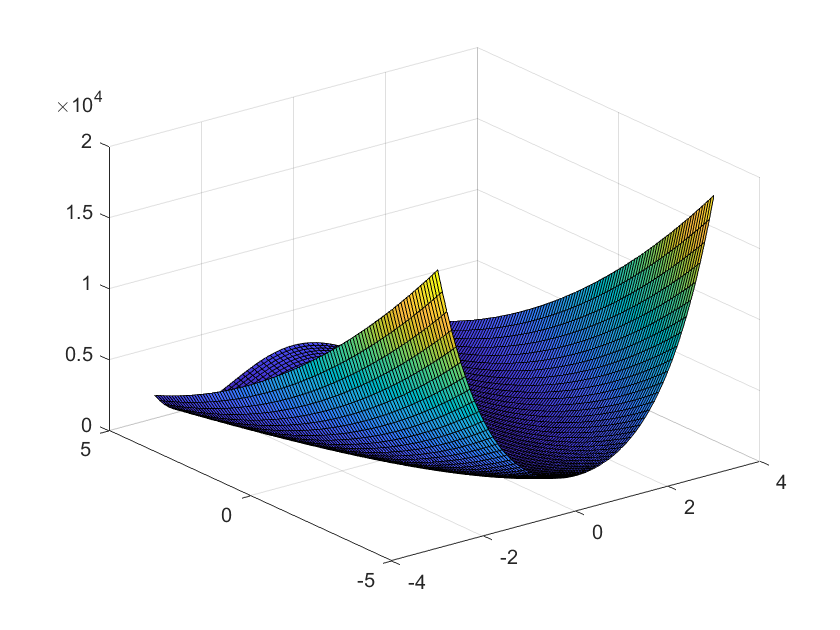

funzioneRosenbrock = @(x) (100*(x(2) - (x(1).^2)).^2 + (1 - x(1)).^2);
gradEsattoRosenbrock = @(x) [-400.*(x(2)-x(1).^2).*x(1) - 2.*(1-x(1));
                            200.*(x(2)-x(1).^2)];

x = -3:.1:3;
y = -5:.1:5;
[X,Y] = meshgrid(x,y); % costruisco le matrici delle coordinate dei nodi.
Z = (100.*(Y - (X.^2)).^2 + (1 - X).^2);
surf(X,Y,Z) %grafico della superficie.

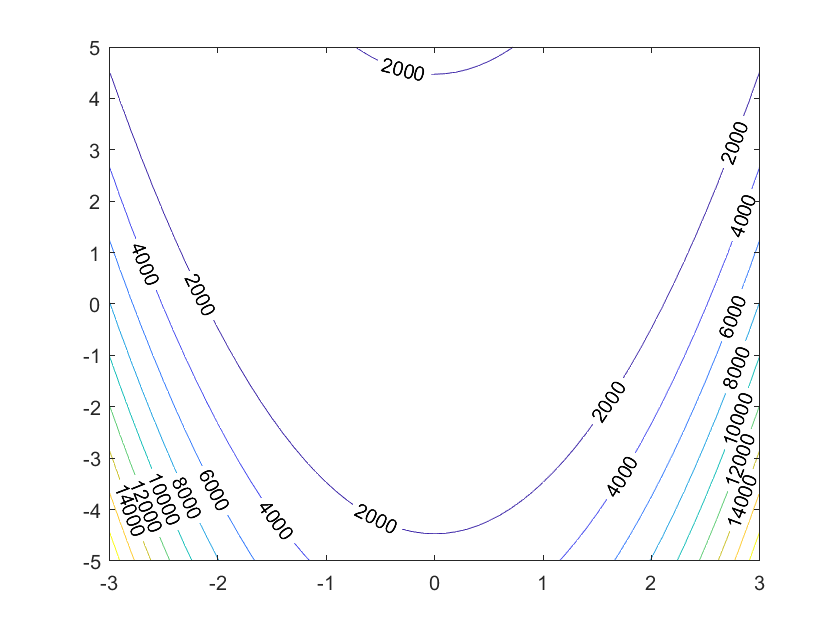

contour(X,Y,Z,'ShowText','on') %curve di livello nel "rettangolo" [-3,3]*[-5,5]

  2. **Elenco dei parametri utilizzati per testare la procedura di line search approssimata****:** dichiaro tre vettori di tre elementi ciascuno, ovvero saranno 3 i valori dei parametri c, t e $\alpha_0 \;$che verranno utilizzati per testare la procedura implementata.

 numeroAlphaZero = 3; 
 numeroParametriC = 3;
 numeroParametriT = 3; 
  
 passoIniziale = [2; 3; 4]; % parametro alpha0
 contrazionePasso = [0.2; 0.5; 0.7]; % parametro c.
 parametroTarget = [0.15; 0.2; 0.3]; % parametro t

 3.** Utilizzo della procedura di backtracking implementata****:** in ognuno dei successivi tre paragrafi, vengono tenuti costanti due parametri , e viene fatto variare il terzo. Dopo tre chiamate della funzione, una per ogni valore assunto dal parametro libero, vengono esposti in forma tabellare i risultati ottenuti, corredati da un breve commento.

*** -  Primo caso: parametri t e c COSTANTI, passo iniziale ***$\alpha_0$*** VARIABILE.***

% creo una tabella contenente i due parametri costanti.
parametriCostanti = table('Size', [1 2], 'VariableTypes', {'double', 'double'}, 'VariableNames', {'ParametroTarget', 'ContrazionePasso'});
parametriCostanti(1,:) = {parametroTarget(1,1), contrazionePasso(1,1)};

%creo una tabella in cui verifico se effetivamente si è
%giunti a convergenza (x e y indicano le coordinate del punto finale)

varTypes = {'double','double', 'double', 'double'};
verificaConvergenza = table('Size', [numeroAlphaZero 4], 'VariableTypes',varTypes,'VariableNames', {'PassoIniziale','x', 'y', 'Norma gradiente'});

%creo una tabella in cui vi sarà il numero di iterazioni
%necessario per arrivare a convergenza al variare del passo iniziale.

risultati = table('Size', [numeroAlphaZero 2], 'VariableTypes', {'double', 'double'}, 'VariableNames', {'PassoIniziale', 'NumeroIterazioni'});

for i = 1:numeroAlphaZero
  [numIterazioni,puntoConvergenza, normaGradienteRosenbrock] = BackTrackingRosenbrock(passoIniziale(i,1), contrazionePasso(1,1), parametroTarget(1,1));
  risultati(i,:) = {passoIniziale(i,1), numIterazioni};
  verificaConvergenza(i,:) = {passoIniziale(i,1),round(puntoConvergenza(1,1),2),round(puntoConvergenza(2,1),2),round(normaGradienteRosenbrock,4)};
end

format short

parametriCostanti

parametriCostanti = 1×2 table
    ParametroTarget    ContrazionePasso
    _______________    ________________

         0.15                0.2       


verificaConvergenza

verificaConvergenza = 3×4 table
    PassoIniziale    x    y    Norma gradiente
    _____________    _    _    _______________

          2          1    1         0.001     
          3          1    1        0.0009     
          4          1    1         0.001     


risultati

risultati = 3×2 table
    PassoIniziale    NumeroIterazioni
    _____________    ________________

          2                4923      
          3                1590      
          4                3978      


- Come si vede nella tabella "verificaConvergenza", si è giunti al punto di minimo (1,1) in ciascuno dei tre casi, e la norma del gradiente è infatti inferiore od uguale alla tolleranza prescelta (pari a ${10}^{-3}$). 

- Il numero di iterazioni necessario per arrivare a convergenza varia sensibilmente al variare del passo iniziale $\alpha_0$ della procedura di backtracking, come esposto nella tabella "risultati".

- La prestazione è dunque sensibile rispetto al modo in cui tale parametro viene settato.

***-  Secondo caso: parametri t e***${\;\alpha }_0$***  COSTANTI,  contrazione del passo c VARIABILE.***

% creo una tabella contenente i due parametri costanti.
parametriCostanti = table('Size', [1 2], 'VariableTypes', {'double', 'double'}, 'VariableNames', {'ParametroTarget', 'PassoIniziale'});
parametriCostanti(1,:) = {parametroTarget(1,1), passoIniziale(2,1)};

%creo una tabella in cui verifico se effetivamente si è
%giunti a convergenza (x e y indicano le coordinate del punto finale)

varTypes = {'double','double', 'double', 'double'};
verificaConvergenza = table('Size', [numeroParametriC 4], 'VariableTypes',varTypes,'VariableNames', {'ContrazionePasso','x', 'y', 'Norma gradiente'});

%creo una tabella in cui vi sarà il numero di iterazioni
%necessario per arrivare a convergenza al variare della contrazione
%del passo.

risultati = table('Size', [numeroParametriC 2], 'VariableTypes', {'double', 'double'}, 'VariableNames', {'ContrazionePasso', 'NumeroIterazioni'});

for i = 1:numeroParametriC
  [numIterazioni,puntoConvergenza, normaGradienteRosenbrock] = BackTrackingRosenbrock(passoIniziale(2,1), contrazionePasso(i,1), parametroTarget(1,1));
  risultati(i,:) = {contrazionePasso(i,1), numIterazioni};
  verificaConvergenza(i,:) = {contrazionePasso(i,1),round(puntoConvergenza(1,1),2),round(puntoConvergenza(2,1),2),round(normaGradienteRosenbrock,4)};
end

format short
parametriCostanti

parametriCostanti = 1×2 table
    ParametroTarget    PassoIniziale
    _______________    _____________

         0.15                3      


verificaConvergenza

verificaConvergenza = 3×4 table
    ContrazionePasso    x    y    Norma gradiente
    ________________    _    _    _______________

          0.2           1    1        0.0009     
          0.5           1    1         0.001     
          0.7           1    1         0.001     


risultati

risultati = 3×2 table
    ContrazionePasso    NumeroIterazioni
    ________________    ________________

          0.2                 1590      
          0.5                 3550      
          0.7                 6252      


- Si è giunti a convergenza in tutti e tre i casi, come indicato nella tabella verificaConvergenza.

- Anche in questo caso, la prestazione è molto sensibile rispetto al settaggio del parametro c  (si veda tabella "risultati") : infatti, notiamo come nel primo caso (t = 0.15, $\alpha_0$ = 3, c = 0.2) il numero di iterazioni, ovvero il numero di volte in cui viene applicata la procedura di backtracking per giungere a convergenza, sia relativamente basso (1590), rispetto al terzo caso (t = 0.15, $\alpha_0$ = 3, c = 0.7), che conta un numero di iterazioni circa 4 volte superiore (6252).

***-  Terzo caso: parametri c e***${\;\alpha }_0$***  COSTANTI,  parametro target t VARIABILE.***

% creo una tabella contenente i due parametri costanti.
parametriCostanti = table('Size', [1 2], 'VariableTypes', {'double', 'double'}, 'VariableNames', {'ContrazionePasso', 'PassoIniziale'});
parametriCostanti(1,:) = {contrazionePasso(1,1), passoIniziale(3,1)};

%creo una tabella in cui verifico se effetivamente si è
%giunti a convergenza (x e y indicano le coordinate del punto finale)

varTypes = {'double','double', 'double', 'double'};
verificaConvergenza = table('Size', [numeroParametriT 4], 'VariableTypes',varTypes,'VariableNames', {'ParametroTarget','x', 'y', 'Norma gradiente'});

%creo una tabella in cui vi sarà il numero di iterazioni
%necessario per arrivare a convergenza al variare del parametro
%target.

risultati = table('Size', [numeroParametriT 2], 'VariableTypes', {'double', 'double'}, 'VariableNames', {'ParametroTarget', 'NumeroIterazioni'});

for i = 1:numeroParametriT
  [numIterazioni,puntoConvergenza, normaGradienteRosenbrock] = BackTrackingRosenbrock(passoIniziale(3,1), contrazionePasso(1,1), parametroTarget(i,1));
  risultati(i,:) = {parametroTarget(i,1), numIterazioni};
  verificaConvergenza(i,:) = {parametroTarget(i,1),round(puntoConvergenza(1,1),2),round(puntoConvergenza(2,1),2),round(normaGradienteRosenbrock,4)};
end

format short
parametriCostanti

parametriCostanti = 1×2 table
    ContrazionePasso    PassoIniziale
    ________________    _____________

          0.2                 4      


verificaConvergenza

verificaConvergenza = 3×4 table
    ParametroTarget    x    y    Norma gradiente
    _______________    _    _    _______________

         0.15          1    1         0.001     
          0.2          1    1         0.001     
          0.3          1    1         0.001     


risultati

risultati = 3×2 table
    ParametroTarget    NumeroIterazioni
    _______________    ________________

         0.15                3978      
          0.2                4230      
          0.3                1300      


- In tutti e tre i casi si è giunti a convergenza: il punto finale è (1,1) , e la norma del gradiente è minore od uguale della tolleranza.

- I risultati ottenuti mostrano ancora una volta come la procedura di backtracking per line search approssimata sia sensibile rispetto alla scelta dei parametri in input, in questo caso rispetto alla scelta del parametro target : se la differenza in termini di iterazioni tra il primo ed il secondo caso è relativamente bassa, il numero di iterazioni diminuisce considerevolmente nel terzo caso (t = 0.3), come si evince dalla tabella "risultati".

**4. Conclusione: commento dei risultati ottenuti.**

In definitiva, si può affermare che la procedura di backtracking per line search approssimata nel metodo steepest descent è molto sensibile rispetto ai parametri settati.

Nel corso dell'esposizione, si è scelto di eseguire un'analisi "statica" dei risultati ottenuti, nel senso che si sono settati due parametri e tenuti come costanti, ed è stato fatto variare il terzo; in tal modo si è già notato come i risultati varino significativamente al variare del terzo parametro "libero". Tuttavia, questo modo di procedere (scelto per una maggiore chiarezza espositiva) è forse "semplificativo", nel senso che, probabilmente, ignora un aspetto "dinamico" importante, ovvero il fatto che i tre parametri sono tra di loro correlati.

In altre parole, la scelta dei due parametri da tenere costanti (e del valore costante che essi devono assumere) è stata arbitraria, e scelte diverse avrebbero portato a risultati molto differenti al variare del terzo parametro libero. 

A tal proposito, riporto un esempio esplicativo: consideriamo nuovamente il caso del parametro target t variabile; tuttavia a differenza di quanto fatto precedentemente ($\alpha_{0\;}$= 4), poniamo il passo iniziale pari a 2. In entrambi i casi, la contrazione del passo c è pari a 0.2 . Raccolgo i risultati cosi ottenuti nella tabella "risultatiBis". 

%% alpha0 = 2.
risultatiBis = table('Size', [numeroParametriT 2], 'VariableTypes', {'double', 'double'}, 'VariableNames', {'ParametroTarget', 'NumeroIterazioni'});
for i = 1:numeroParametriT
  [numIterazioni,puntoConvergenza, normaGradienteRosenbrock] = BackTrackingRosenbrock(passoIniziale(1,1), contrazionePasso(1,1), parametroTarget(i,1));
  risultatiBis(i,:) = {parametroTarget(i,1), numIterazioni};
end

passoSceltoBis = table('Size', [1 1], 'VariableTypes', {'double'},'VariableNames', {'PassoInizialeScelto'});
passoSceltoBis(1,1) = {passoIniziale(1)}

passoSceltoBis = table
    PassoInizialeScelto
    ___________________

             2         


risultatiBis

risultatiBis = 3×2 table
    ParametroTarget    NumeroIterazioni
    _______________    ________________

         0.15                4923      
          0.2                5172      
          0.3                6024      


%%alpha0 = 4: riporto cioè nuovamente i risultati ottenuti precedentemente
%%con alpha0 = 4.
passoScelto = table('Size', [1 1], 'VariableTypes', {'double'},'VariableNames', {'PassoInizialeScelto'});
passoScelto(1,1) = {passoIniziale(3,1)}

passoScelto = table
    PassoInizialeScelto
    ___________________

             4         


risultati

risultati = 3×2 table
    ParametroTarget    NumeroIterazioni
    _______________    ________________

         0.15                3978      
          0.2                4230      
          0.3                1300      


Come si può notare dal confronto delle due tabelle, i risultati variano sensibilmente al variare del passo iniziale che (arbitrariamente) poniamo costante, ed il valore del parametro target "ottimale", ovvero che ci consente di arrivare prima a convergenza, varia anch'esso: se nel caso $\alpha_0$ = 4, il valore t = 3 è in tal senso il migliore (1300 iterazioni), nel caso $\alpha_0$ = 2, il valore t = 3 è di gran lunga il "peggiore", con addirittura 6024 iterazioni.

Tale aspetto "dinamico" dei tre parametri, che riflette appunto la loro interrelazione, rende probabilmente ancora più sensibile ai dati passati in input la procedura di backtracking e, conseguentemente, la ricerca del minimo di una data funzione.

`Implementazione della procedura di backtracking nel metodo steepest descent per la funzione di Rosenbrock.`

La funzione prende in input i tre parametri $\alpha_0$, t e c, e restituisce in output il numero di iterazioni totali (ovvero il numero di volte in cui si è applicata la procedura di backtracking nel metodo steepest descent prima di arrivare a convergenza), il punto di convergenza, ovvero il punto finale in cui ci si ferma, e la norma $l_{\infty }$ del gradiente della funzione in tale punto (che vorremmo minore od uguale della tolleranza).

Si è scelto di fissare il punto iniziale della ricerca pari a (-1.9 , 2.0), di definire una tolleranza sulla norma del gradiente pari a ${10}^{-3}$, ed un numero di iterazioni massimo pari a 8500.

Nel caso della funzione di Rosenbrock (in due dimensioni), il punto di convergenza (ossia il minimo) deve essere il punto (1,1), nel quale essa è identicamente nulla.

function [numIterazioni,puntoConvergenza,normaGradienteRosenbrock] = BackTrackingRosenbrock(passoIniziale, contrazionePasso, parametroTarget)
  
  funzioneRosenbrock = @(x) (100*(x(2) - (x(1).^2)).^2 + (1 - x(1)).^2);
  
  %% Definisco ora il gradiente.
  
  gradEsattoRosenbrock = @(x) [-400.*(x(2)-x(1).^2).*x(1) - 2.*(1-x(1));
                            200.*(x(2)-x(1).^2)];
                        
  puntoIniziale = [-1.9; 2.0];
  tolleranza = 1e-3;
  iterazioniMax = 8500;
  punto = puntoIniziale;
  passo = passoIniziale;
  fineCiclo = 0;
 
  for i = 1:iterazioniMax
 
        if(norm(gradEsattoRosenbrock(punto),inf) <= tolleranza)
            %% cio significa che, almeno in teoria, sono giunto a convergenza
            fineCiclo = 1;
            break;
        end
     
        if(fineCiclo == 0)
         
         %% Se entro in questo if, devo proseguire nella ricerca.
         passo = passoIniziale;
         
         while (funzioneRosenbrock(punto - passo*gradEsattoRosenbrock(punto)) > funzioneRosenbrock(punto) - parametroTarget*passo*((norm(gradEsattoRosenbrock(punto))).^2))
             %% finche questa disuguaglianza è vera, allora contraggo il passo
             %% fino a trovare il nuovo punto.
             passo = passo*contrazionePasso;
         end
         
         %%aggiorno il punto, con il passo ottenuto dalla line search
         %%approssimata.
         punto = punto - passo*gradEsattoRosenbrock(punto);
        end    
  end
  numIterazioni = i;
  puntoConvergenza = punto;
  normaGradienteRosenbrock = norm(gradEsattoRosenbrock(punto),inf);
  
end